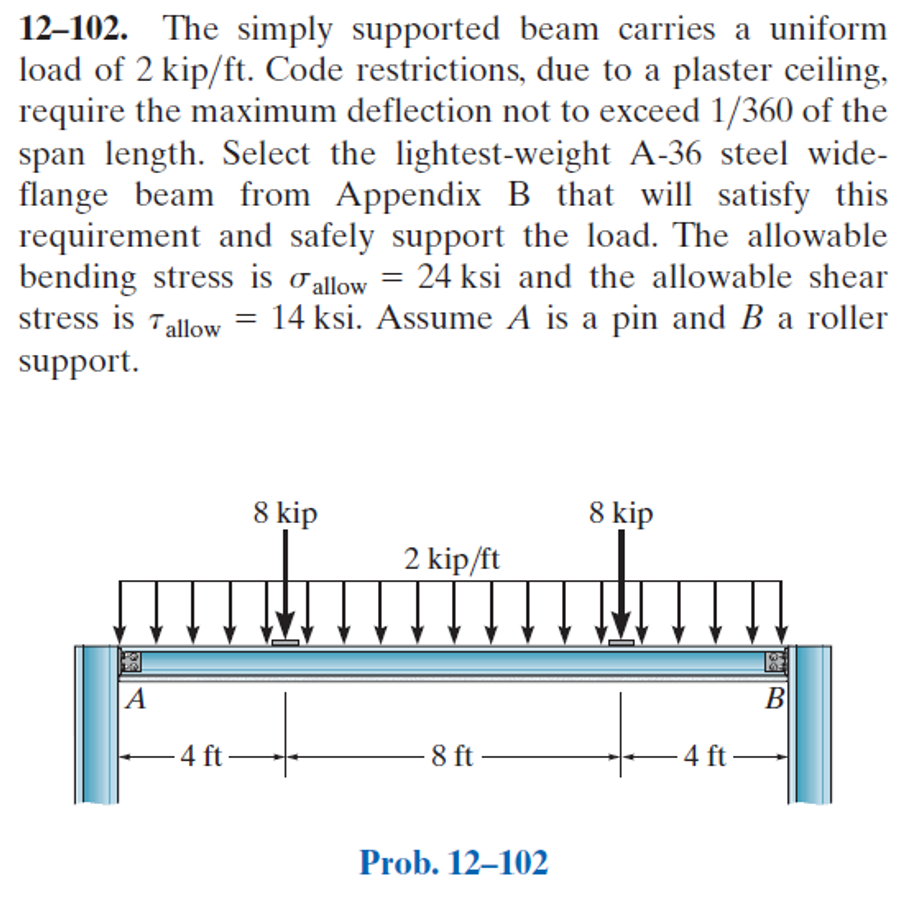

# allowable stresses and deflections

u = symunit;
sigma_allow = 24*u.ksi;
tau_allow = 14*u.ksi;
y_allow = 16*u.ft/360;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 16*u.ft);
b = b.add('applied', 'force', -8*u.kip, 4*u.ft);
b = b.add('applied', 'force', -8*u.kip, 12*u.ft);
b = b.add('distributed', 'force', -2*u.kip/u.ft, [0 16]*u.ft);
b.L = 16*u.ft;

# section properteis

b.E = rewrite(29e6*u.psi, [u.kip u.ft]);

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x^{3}-48\,x^{2}\,\mathrm{ft}+6400\,{\mathrm{ft}}^{3}\right)}{50112000\,\text{I}}\,\mathrm{ft} & \text{ if }x\leq 4\,\mathrm{ft}\\ \frac{-x^{4}+32\,x^{3}\,\mathrm{ft}+192\,x^{2}\,{\mathrm{ft}}^{2}-7168\,x\,{\mathrm{ft}}^{3}+1024\,{\mathrm{ft}}^{4}}{50112000\,\text{I}}\,\mathrm{ft} & \text{ if }x\in \left(4\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\frac{\left(x-16\,\mathrm{ft}\right)\,\left(x^{3}-768\,x\,{\mathrm{ft}}^{2}+1792\,{\mathrm{ft}}^{3}\right)}{50112000\,\text{I}}\,\mathrm{ft} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{x^{3}-36\,x^{2}\,\mathrm{ft}+1600\,{\mathrm{ft}}^{3}}{12528000\,\text{I}}\,\mathrm{ft} & \text{ if }x\leq 4\,\mathrm{ft}\\ \frac{\left(x-8\,\mathrm{ft}\right)\,\left(-x^{2}+16\,x\,\mathrm{ft}+224\,{\mathrm{ft}}^{2}\right)}{12528000\,\text{I}}\,\mathrm{ft} & \text{ if }x\in \left(4\,\mathrm{ft},12\,\mathrm{ft}\right]\\ \frac{-x^{3}+12\,x^{2}\,\mathrm{ft}+384\,x\,{\mathrm{ft}}^{2}-3520\,{\mathrm{ft}}^{3}}{12528000\,\text{I}}\,\mathrm{ft} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -x\,\left(x-24\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 4\,\mathrm{ft}\\ \left(-x^{2}+16\,x\,\mathrm{ft}+32\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(4\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -\left(x+8\,\mathrm{ft}\right)\,\left(x-16\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -2\,\left(x-12\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 4\,\mathrm{ft}\\ -2\,\left(x-8\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\in \left(4\,\mathrm{ft},12\,\mathrm{ft}\right]\\ -2\,\left(x-4\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = -2\,\frac{\mathrm{kip}}{\mathrm{ft}}$$

addvar(y);

# reactions

Ra = r.Ra %#ok

$$Ra = 24\,\mathrm{kip}$$

Rb = r.Rb %#ok

$$Rb = 24\,\mathrm{kip}$$

clear Ra Rb;

# shear and moment diagram

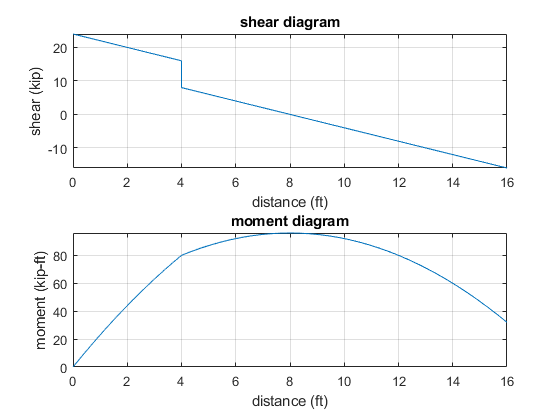

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum bending bending moment

M_max = m(8*u.ft);
S_reqd = rewrite(M_max/sigma_allow, u.in);

# maximum deflection